# COMSOL Plotter

Goal of this code is to extract and plot COMSOL outputs, manipulating them in ways not possiple with COMSOL


cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\COMSOL Analysis'

addpath( ...
    'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1', ... % Time domain analysis from GaN paper
    'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
    'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
    'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\SMA Injection'); %new comsol stuff
    

load('ImpVariables.mat')


## File Setup

freqMin = 0.05*c.giga;
freqMax = 10*c.giga;
freqStep = 0.05*c.giga;
field.freq = freqMin:freqStep:freqMax;
sizeAr = size(field.freq)

## 2D Data Importer

filename = 'xField_topPlane_grid.txt'
data=readtable(filename,'HeaderLines',9);
data=table2array(data);
field.x = data(1,1);
field.y = data(:,2);
field.z = data(:,3);
field.Ex = data(:,4:end).';

## Reshape to Mesh Grid Approach

freqSelect = 4;
numPts = 201;
fieldPlot.y = field.y(1:numPts);
fieldPlot.Ex = reshape(field.Ex(3+freqSelect,:),[201,201]);
pcolor(real(fieldPlot.y), real(fieldPlot.y), abs(fieldPlot.Ex));
shading interp;

%plot3(field.y, field.z, field.Ex(4,:)),'o';

% % NO DC TERM IN RAW!
% field.freq = (data(:,1)).';
% field.posX 


## Raw Vector Approach

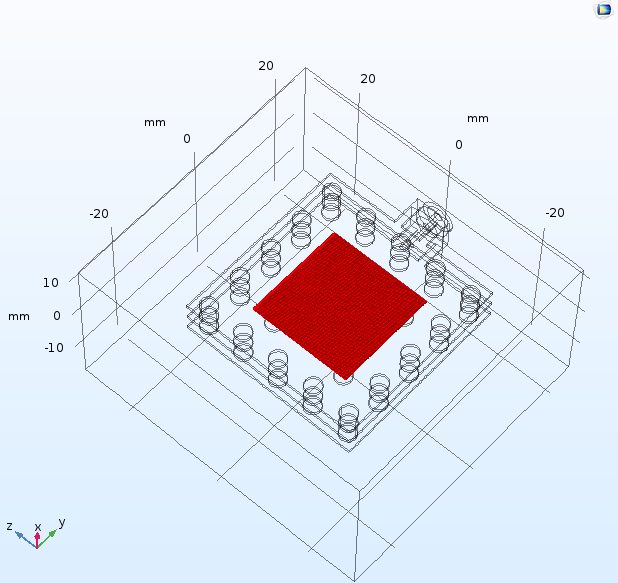

freqSelect = 118;
disp(['Chosen Frequency: ', num2str(field.freq(freqSelect)/c.giga), ' GHz'])


pointsize = 20;
fieldDC_Norm = abs(field.Ex(1,:)/field.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner

%Normalized field to corner point 1 either directly plotted or as
%difference
fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

%fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

scatter3(real(field.y(:)), real(field.z(:)), fieldPlot , pointsize, fieldPlot) 
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
view([0 90]);
shading interp;
colormap(parula)
colorbar
%caxis([-1,0])

## Line Plot Input

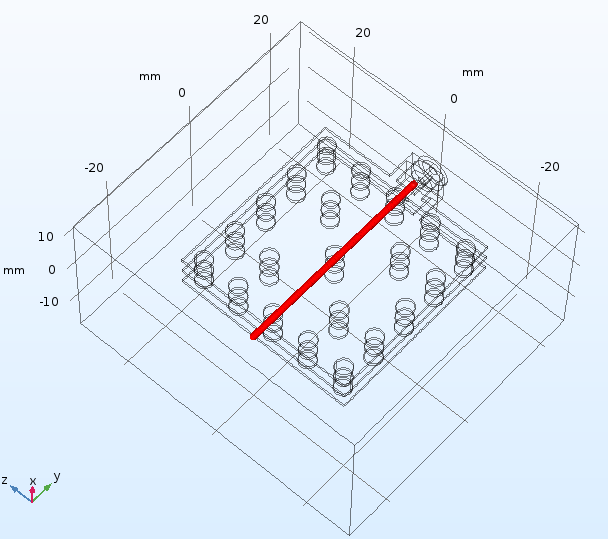

filename = 'xField_PropAxis_grid.txt'
data=readtable(filename,'HeaderLines',9);
data=table2array(data);
sizeAr = size(data);
sizeY = sizeAr(1) ; % no header we remove
sizeF = sizeAr(2) - 3; %3 dimension columns we remove

propField.freq = field.freq;
propField.x = data(1,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:end);


% Manipulate
yRange = 1:401;
sizeYrange = size(yRange);
sizeYrange = sizeYrange(2)

freqRange = 1:100;

normField = abs(propField.Ex(yRange,:));

rescaleIndex =200;

normFieldRescaled = zeros(sizeYrange, sizeF);
%maxField = 1000;
for index = 1:sizeF
    normFieldRescaled(:,index) = normField(:,index)/abs(normField(rescaleIndex,index));
%     if(maxField < normFieldRescaled(end,index))
%         normFieldRescaled(:,index) = normFieldRescaled(:,index-1);
%     end
end

% Plot
plotField = log(normFieldRescaled)%.* real(propField.Ex)./abs(real(propField.Ex));
pcolor(real(propField.y(yRange)), (real(propField.freq)/c.giga), (plotField).');
shading interp;
colorbar;
caxis([-4,10])
xlabel('Position (mm)')
ylabel('Frequency (GHz)')
ylim([0,10])
%xlim([-10,10])
%clabel('Field Strength (V/m')

## Deflection Magnitude/Phase Plots

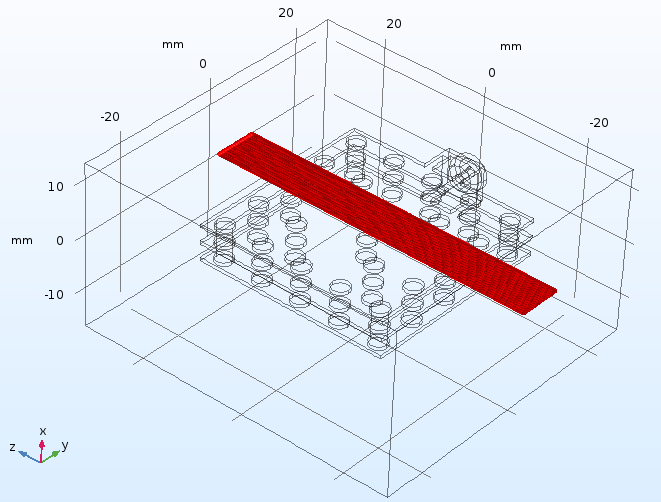

% Import
filename = 'xField_deflPaths_grid.txt'
data=readtable(filename,'HeaderLines',9);
data=table2array(data);
sizeAr = size(data);
sizeY = sizeAr(1) ; % no header we remove
sizeF = sizeAr(2) - 3; %3 dimension columns we remove

deflField.freq = field.freq;
deflField.x = data(1,1);

% shape y
deflField.y = data(:,2);
yNum = ((deflField.y(end))-(deflField.y(1)))/(deflField.y(2)-deflField.y(1))+1;
deflField.y = deflField.y(1:yNum);

% shape z
deflField.z = data(:,3);
zNum = ((deflField.z(end))-(deflField.z(1)))/(deflField.z(1+yNum)-deflField.z(1))+1;
deflField.z = deflField.z(1:yNum:end);


% shape field and plot
freqSelect = 10;
disp(['Chosen Frequency: ', num2str(field.freq(freqSelect)/c.giga), ' GHz']);

Chosen Frequency: 0.5 GHz


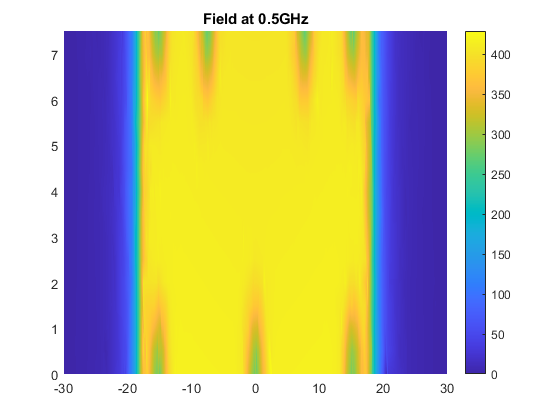


deflField.Ex = data(:,4:end).';
deflField.Ex = reshape(deflField.Ex(freqSelect,:),yNum,[]);
pcolor(real(deflField.z), real(deflField.y), abs(deflField.Ex).*(sign(real(deflField.Ex))))
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
shading interp;
colorbar;

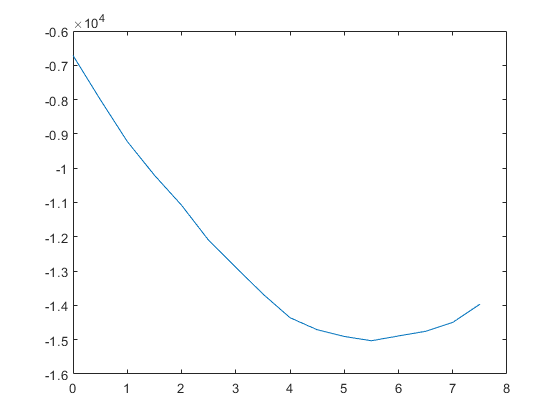

% Plot deflection as frequency and position
freqMax = 200;

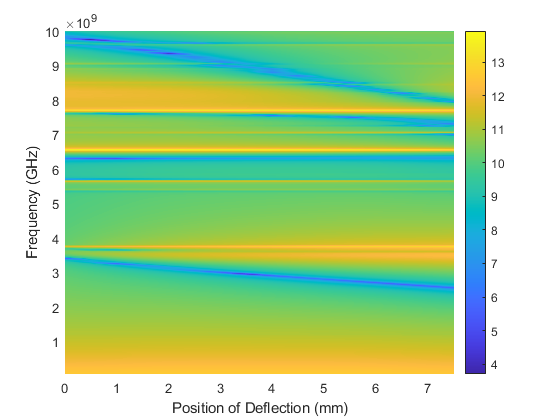

for freqSelect = 1:freqMax
    deflField.Ex = data(:,4:end).';
    deflField.Ex = reshape(deflField.Ex(freqSelect,:),yNum,[]);
    defl(:,freqSelect) = sum(deflField.Ex,2);
end

pcolor(real(deflField.y), real(deflField.freq(1:freqMax)),   log(abs(defl)).') %(sign(real(defl)).*abs(defl)).'
shading interp;
colorbar;
xlabel('Position of Deflection (mm)')
ylabel('Frequency (GHz)')


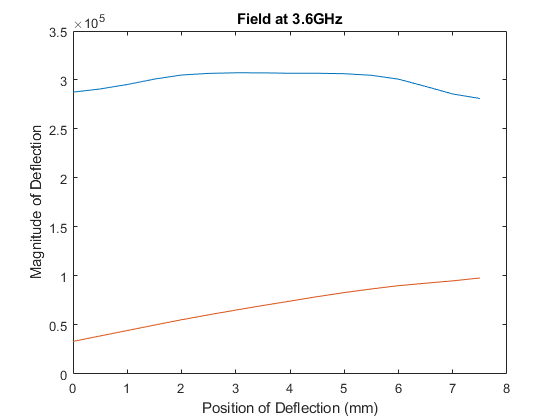

% Plot individual field
freqSelect = 72;
plot(deflField.y, abs(defl(:,[1, freqSelect])))
title(['Field at ', num2str(field.freq(freqSelect)/c.giga), 'GHz'])
xlabel('Position of Deflection (mm)')
ylabel('Magnitude of Deflection')

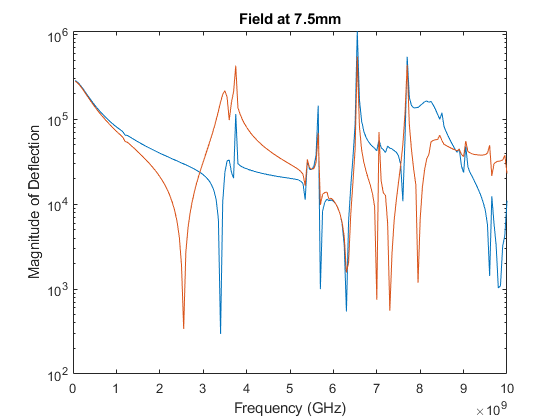

% Plot point as frequency
ySelect = 16;
semilogy(deflField.freq.', abs(defl([1,ySelect],:)))
title(['Field at ', num2str(deflField.y(ySelect)), 'mm'])
xlabel('Frequency (GHz)')
ylabel('Magnitude of Deflection')

## Side Plot

filename = 'xField_sidePlane_grid.txt'
data=readtable(filename,'HeaderLines',9);
data=table2array(data);
propField.x = data(:,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:end).';

pointsize = 100;
fieldPlot = abs(propField.Ex(1,:)/propField.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner


scatter3(real(propField.y(:)), real(propField.x(:)), fieldPlot , pointsize, fieldPlot, '.') 
view([0 90]);
shading interp;